# REPRODUCTION OF THE GRAPHS FROM GEENEN ET AL 2012

% BY THIERRY D.G.A. MONDEEL BASED ON WORK BY SHINTARO NAKAYAMA AND HANS WESTERHOFF
% UNIVERSITY OF AMSTERDAM
% 2017 - 2019

% plotting
fontname = 'Helvetica'; 
set(0,'DefaultAxesFontName',fontname,'DefaultTextFontName',fontname);
set(0,'DefaultAxesFontSize',16,'DefaultTextFontSize',16);

load('../Data/geenen_2012_parameter_scan_results.mat')
D = geenen_2012_parameter_scan;

% order of D's columns: paracetamol, methionine, GSH, J_OPA, J_OXO, v10
% order of D's rows: methione = 1, 15, 30, 60, 100, (random samples), 150

ind1 = D(:,2)==1; % methionine 1 uM
ind15 = D(:,2)==15; % methionine 15 uM
ind30 = D(:,2)==30; % methionine 30 uM
ind60 = D(:,2)==60; % methionine 60 uM
ind100 = D(:,2)==100; % methionine 100 uM
ind150 = D(:,2)==150; % methionine 150 uM


## Figure 2: Glutathione vs. Paracetamol + Geenen Figure 8, 6 and 7

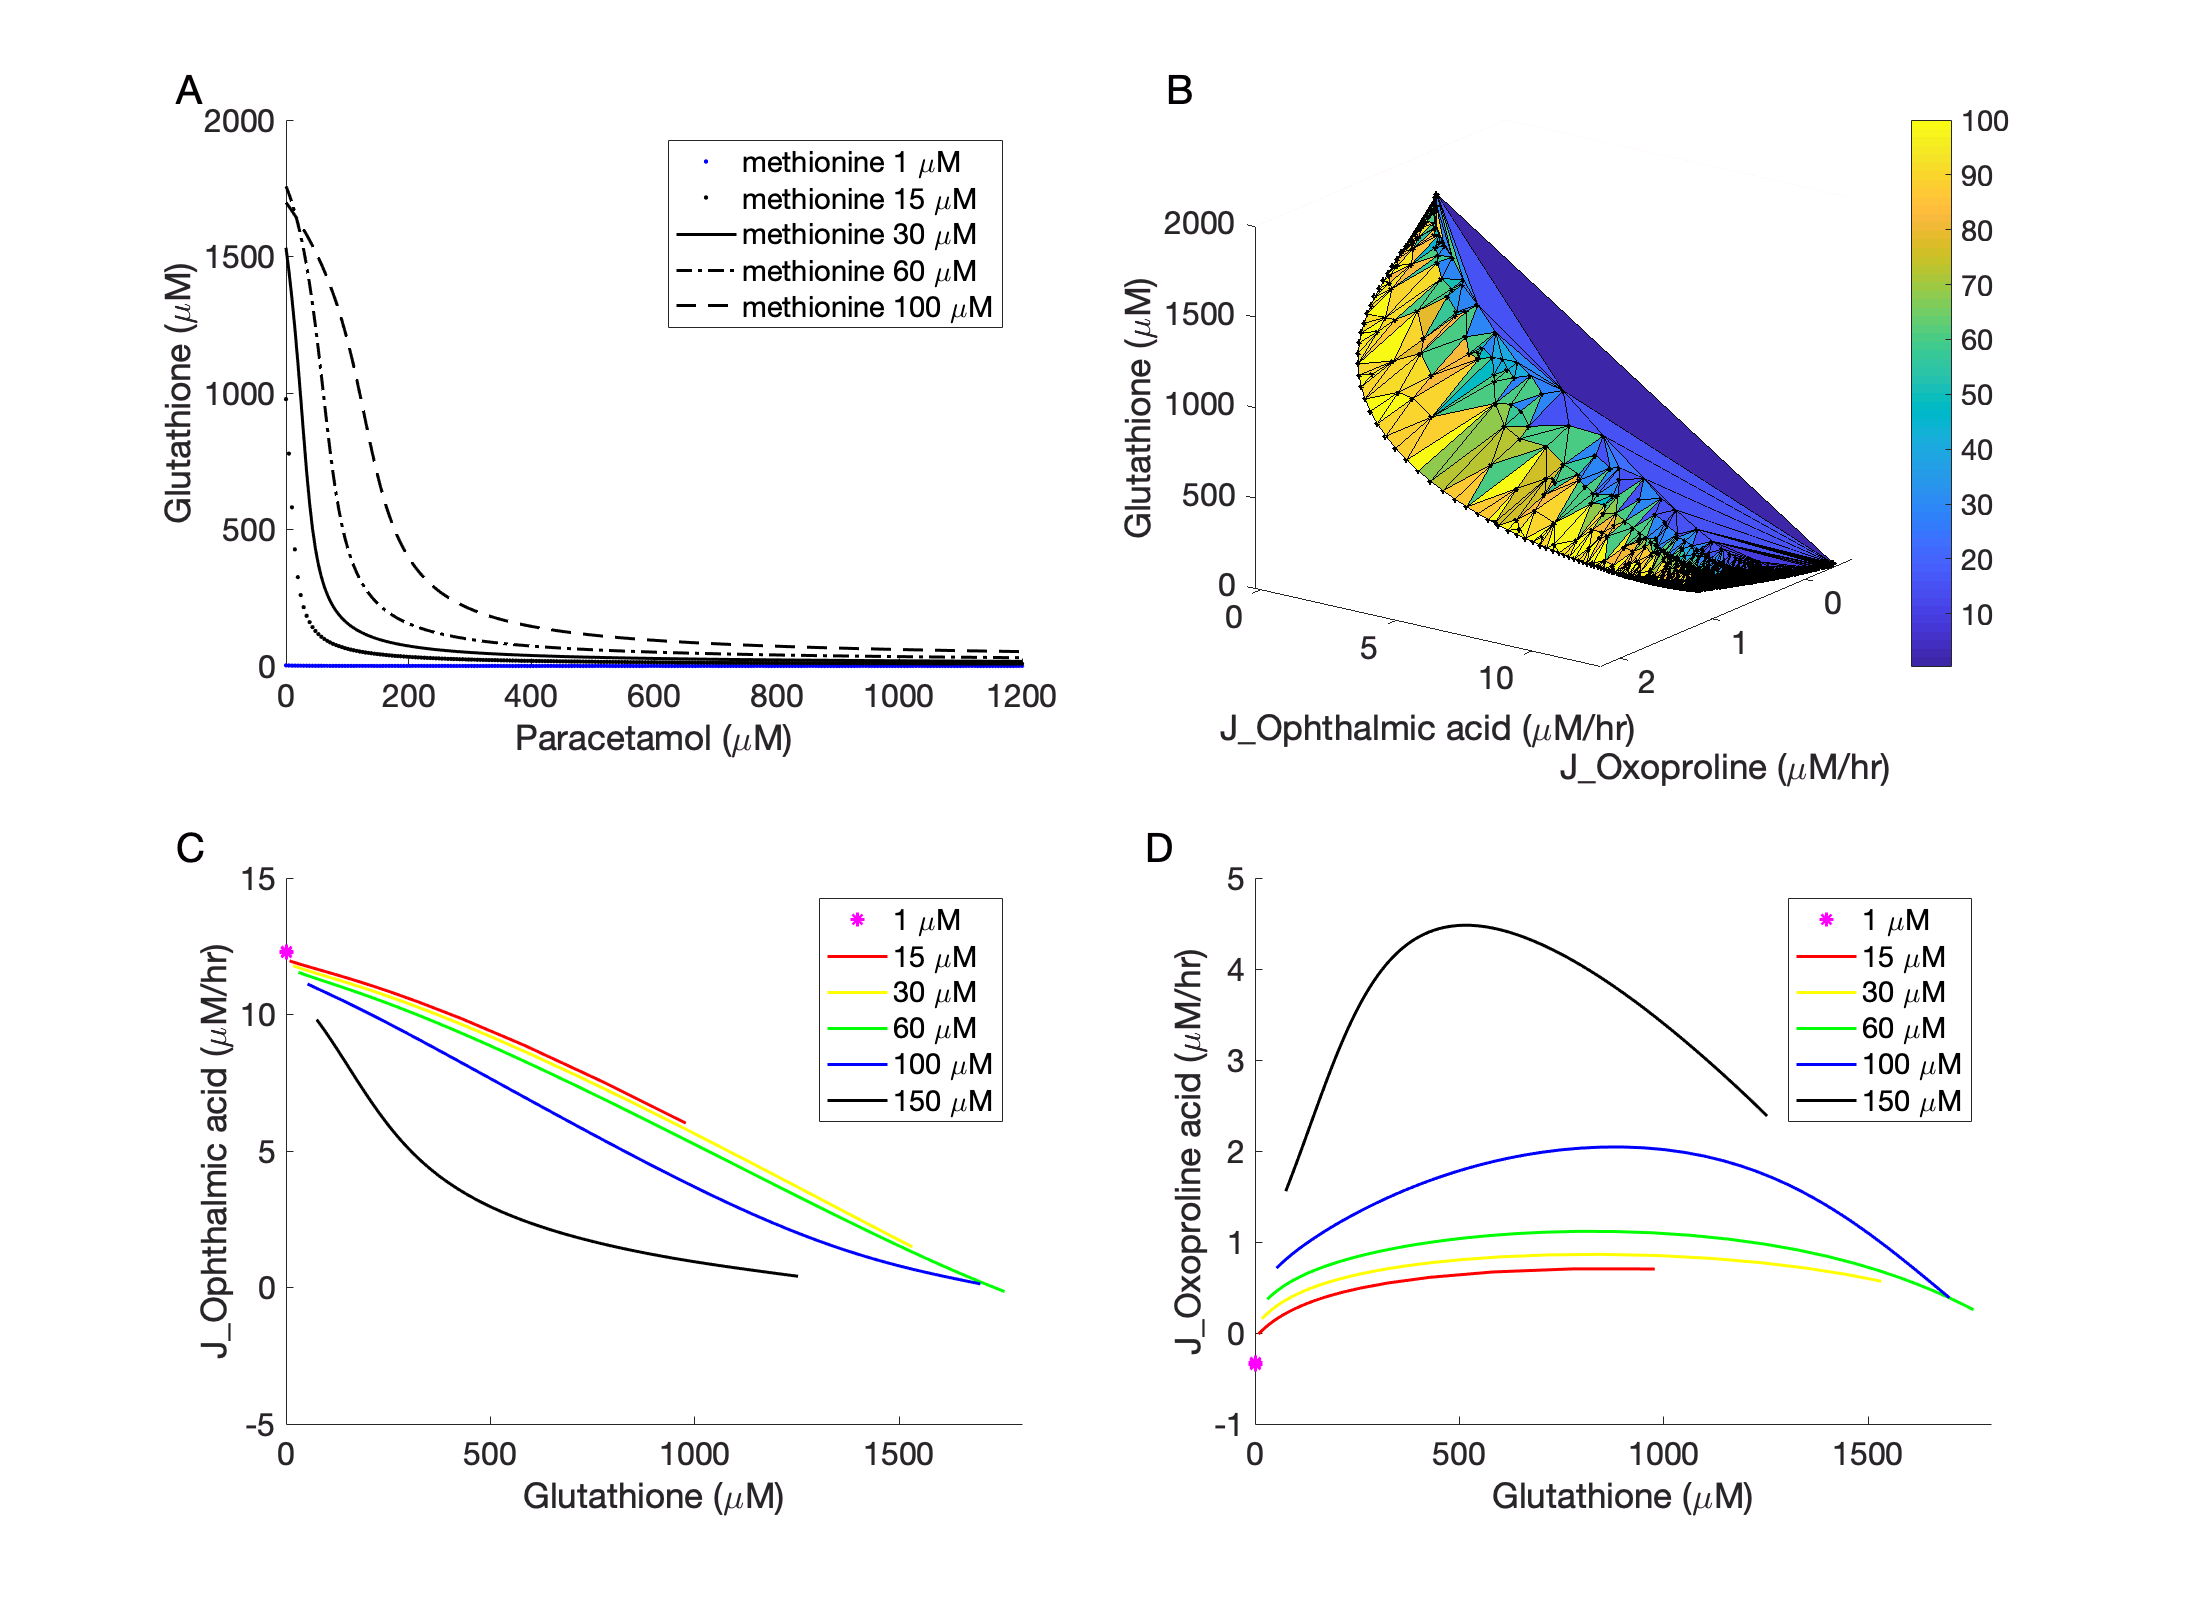

figure('position',[0, 0, 1100, 800])
subplot(2,2,1)
text(-0.15,1.1,'A','Units', 'Normalized', 'VerticalAlignment', 'Top', 'FontSize', 20); hold on
plot(D(ind1,1),D(ind1,3),'b.',D(ind15,1),D(ind15,3),'k.',D(ind30,1),D(ind30,3),'k-',D(ind60,1),D(ind60,3),'k-.',D(ind100,1),D(ind100,3),'k--')
% axis([min(-0.5,min(x)) 1.25*max(x) min(y) 1.1*max(y)])
xlabel('Paracetamol (\muM)')
ylabel('Glutathione (\muM)')
legend('methionine 1 \muM','methionine 15 \muM','methionine 30 \muM','methionine 60 \muM','methionine 100 \muM')
hold off;

% Fig. 8: 3D plot of OPA vs. OXO vs GSH colored by methionine levels
subplot(2,2,2)
text(-0.15,1.1,'B','Units', 'Normalized', 'VerticalAlignment', 'Top', 'FontSize', 20); hold on
% plot these curves only for methionine in [0-100]
ind = D(:,2) < 150;
x = D(ind,4); % OPA
y = D(ind,5); % OXO
z = D(ind,3); % glutathione
C = D(ind,2); % methionine
% delaunay is used to create a Delaunay triangulation of a set of points 
%     in 2D/3D space. A 2D Delaunay triangulation ensures that the circumcircle 
%     associated with each triangle contains no other point in its interior. 
%     This definition extends naturally to higher dimensions. 
%  
%     TRI = delaunay(X,Y) creates a 2D Delaunay triangulation of the points 
%     (X,Y), where X and Y are column-vectors. TRI is a matrix representing 
%     the set of triangles that make up the triangulation. The matrix is of
%     size mtri-by-3, where mtri is the number of triangles. Each row of TRI
%     specifies a triangle defined by indices with respect to the points.
tri = delaunay(x,y); %x,y,z column vectors

trisurf(tri,x,y,z,C);
% shading interp
view(-36,-20)
xlabel('J\_Ophthalmic acid (\muM/hr)'); xlim([-0.2 12.5])
ylabel('J\_Oxoproline (\muM/hr)'); ylim([-0.5 2.2])
zlabel('Glutathione (\muM)'); zlim([0 2000])
colorbar

hLine = plot3(x,y,z,'ko');
% make transparent: http://undocumentedmatlab.com/blog/plot-markers-transparency-and-color-gradient
hLine.MarkerFaceColor = [0.5,0.5,0.5]; 
hLine.MarkerSize = 2;
drawnow
hMarkers = hLine.MarkerHandle;
hMarkers.FaceColorType = 'truecoloralpha';
hMarkers.FaceColorData = uint8(255*[0;0;0;0.2]);

hold off;
grid off

% Fig. 6: GSH to OPA for varying methionine
subplot(2,2,3)
text(-0.15,1.1,'C','Units', 'Normalized', 'VerticalAlignment', 'Top', 'FontSize', 20); hold on
plot(D(ind1,3),D(ind1,4),'m*',D(ind15,3),D(ind15,4),'r',D(ind30,3),D(ind30,4),'y',D(ind60,3),D(ind60,4),'g',D(ind100,3),D(ind100,4),'b',D(ind150,3),D(ind150,4),'k')
xlabel('Glutathione (\muM)'); xlim([0 1800])
ylabel('J\_Ophthalmic acid (\muM/hr)')
legend('1 \muM','15 \muM','30 \muM','60 \muM','100 \muM','150 \muM')
hold off; 

% Fig. 7: GSH to OXO for varying methionine
subplot(2,2,4)
text(-0.15,1.1,'D','Units', 'Normalized', 'VerticalAlignment', 'Top', 'FontSize', 20); hold on
plot(D(ind1,3),D(ind1,5),'m*',D(ind15,3),D(ind15,5),'r',D(ind30,3),D(ind30,5),'y',D(ind60,3),D(ind60,5),'g',D(ind100,3),D(ind100,5),'b',D(ind150,3),D(ind150,5),'k')
xlabel('Glutathione (\muM)'); xlim([0 1800])
ylabel('J\_Oxoproline acid (\muM/hr)')
legend('1 \muM','15 \muM','30 \muM','60 \muM','100 \muM','150 \muM')
hold off;

export_fig('../Figures/Figure_2','-pdf','-r200')

## Figure S1: Glutathione vs. Paracetamol + Reproduce Figures 2-4 from (Geenen, 2012)

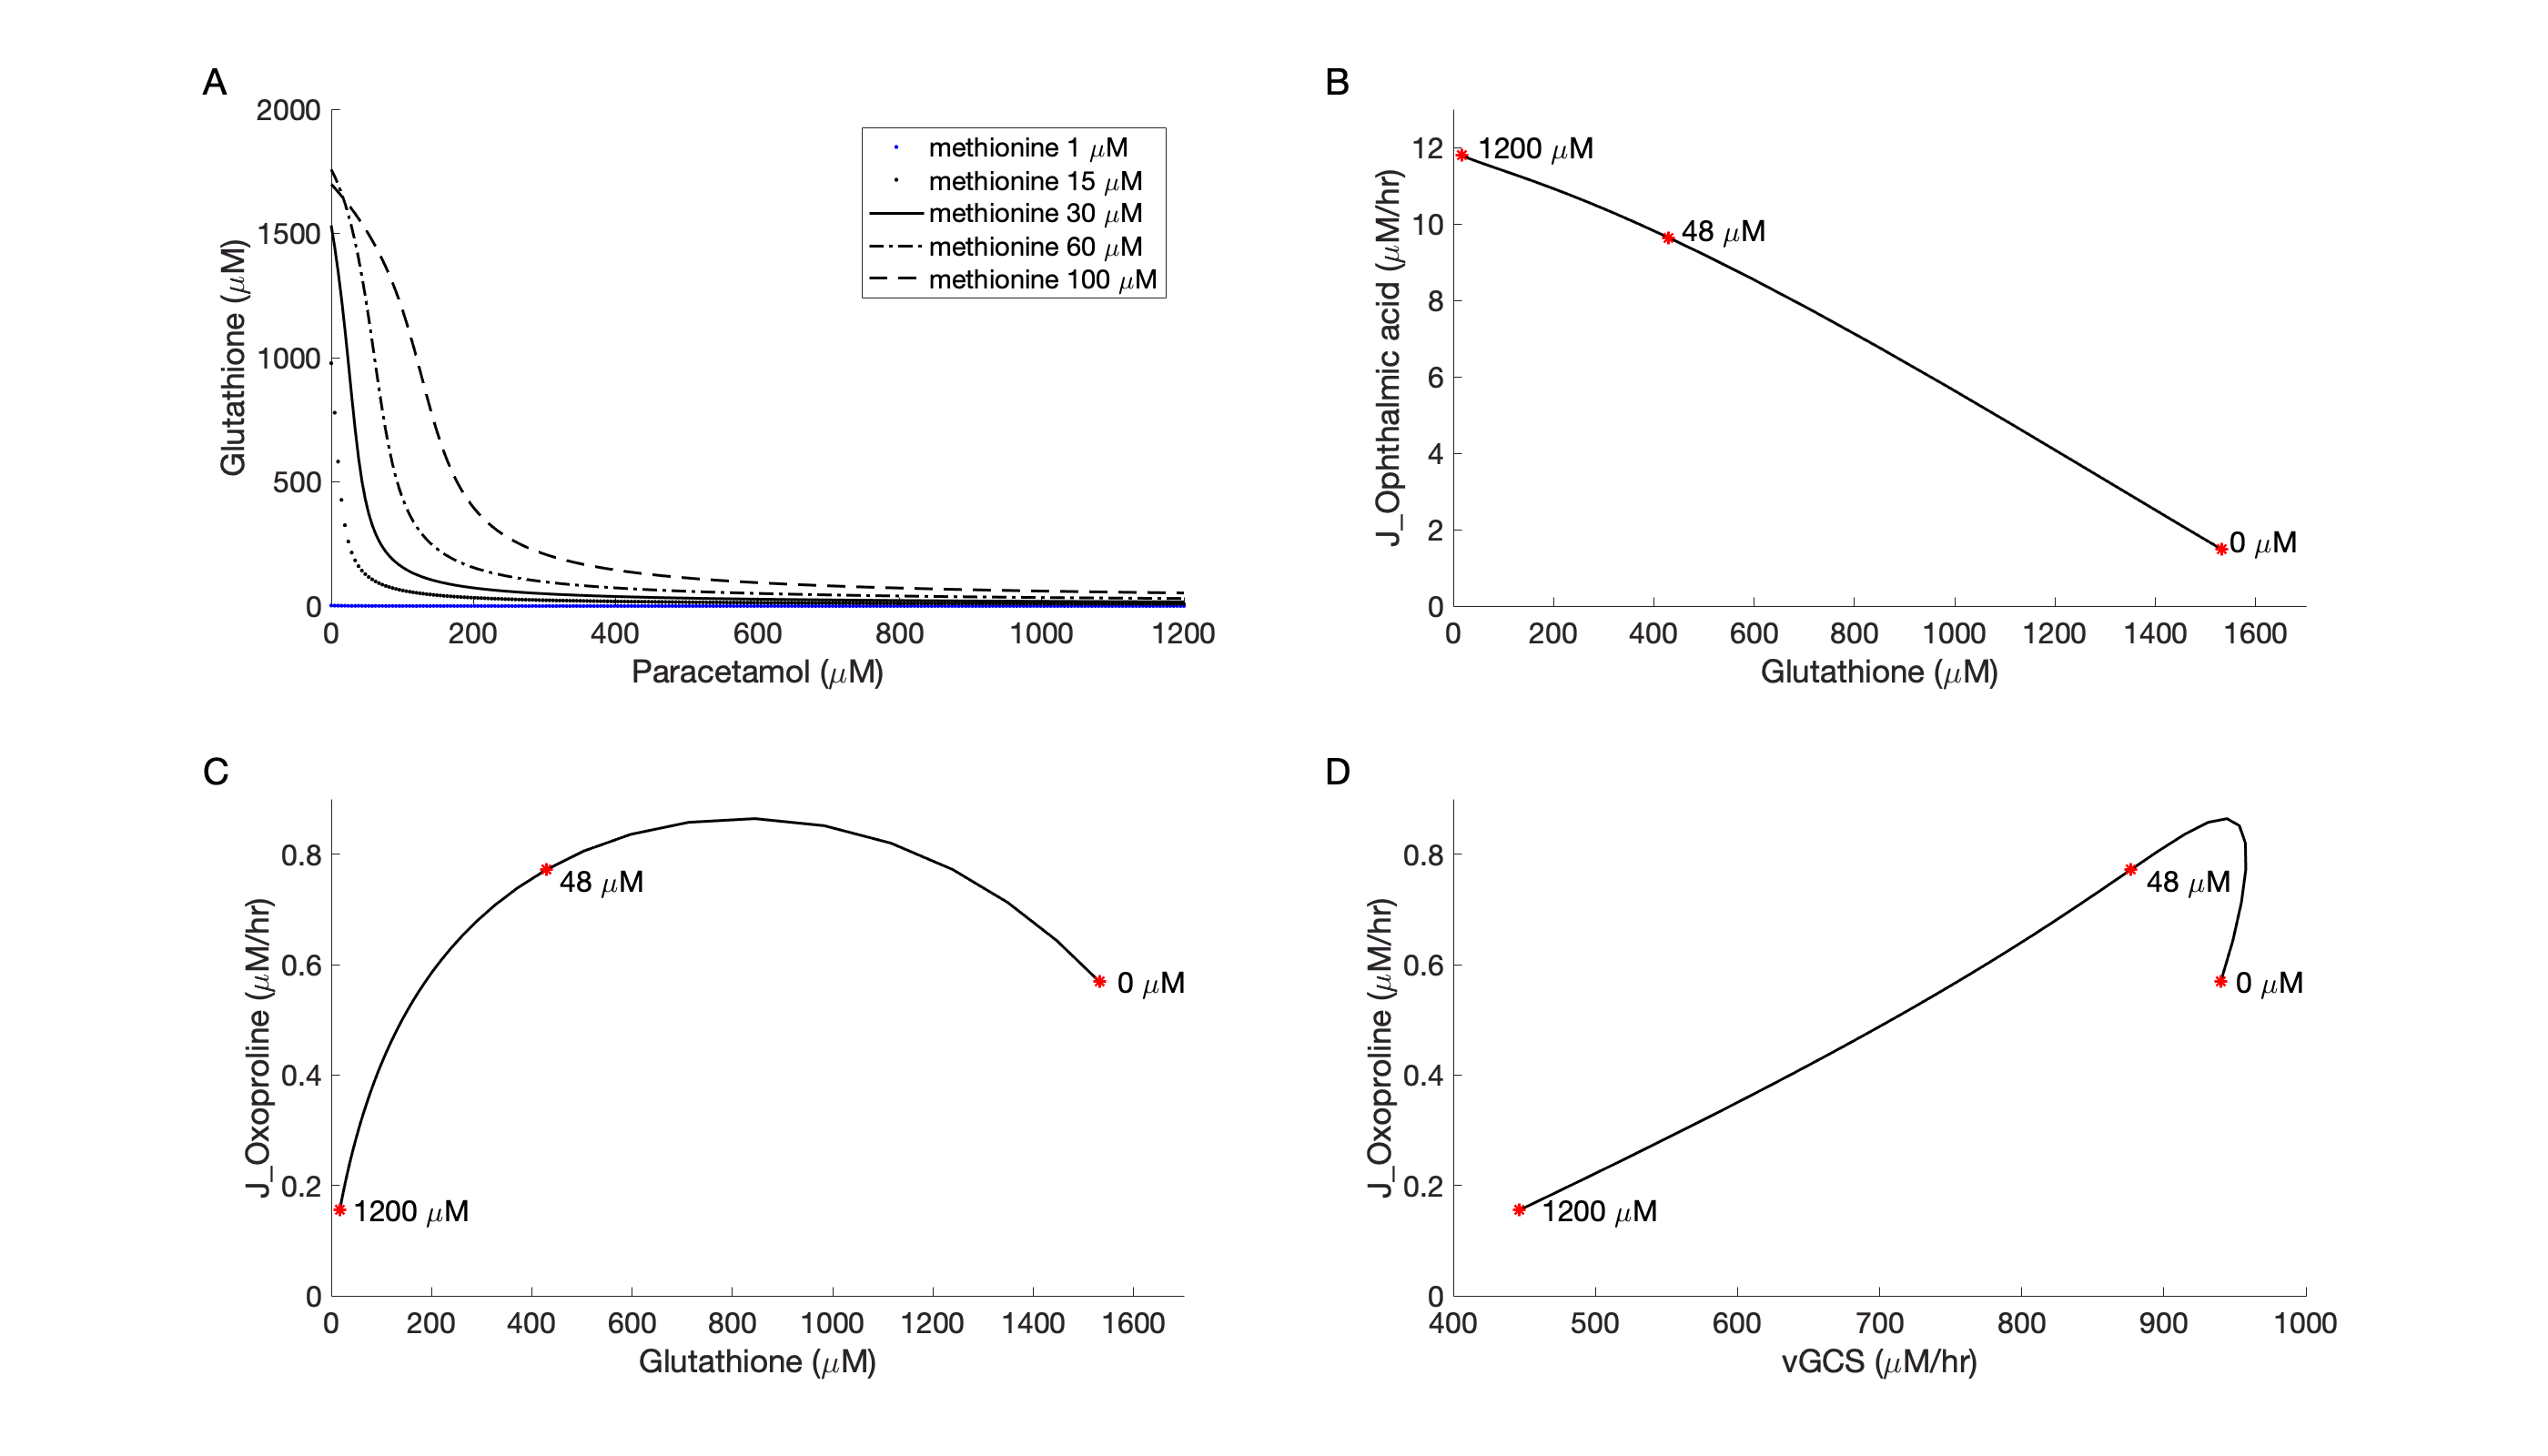

figure('position',[0, 0, 1400, 800])
subplot(2,2,1)
text(-0.15,1.1,'A','Units', 'Normalized', 'VerticalAlignment', 'Top', 'FontSize', 20); hold on
plot(D(ind1,1),D(ind1,3),'b.',D(ind15,1),D(ind15,3),'k.',D(ind30,1),D(ind30,3),'k-',D(ind60,1),D(ind60,3),'k-.',D(ind100,1),D(ind100,3),'k--')
% axis([min(-0.5,min(x)) 1.25*max(x) min(y) 1.1*max(y)])
xlabel('Paracetamol (\muM)')
ylabel('Glutathione (\muM)')
legend('methionine 1 \muM','methionine 15 \muM','methionine 30 \muM','methionine 60 \muM','methionine 100 \muM')
hold off;

% Fig. 2: GSH vs OPA
subplot(2,2,2) % paracetamol [0,1200] and met = 30
text(-0.15,1.1,'B','Units', 'Normalized', 'VerticalAlignment', 'Top', 'FontSize', 20); hold on
x = D(ind30,3);
y = D(ind30,4);
plot(x,y,'k')
axis([min(-0.5,min(x)) 1.25*max(x) min(y) 1.1*max(y)])
xlabel('Glutathione (\muM)')
ylabel('J\_Ophthalmic acid (\muM/hr)')
txt1 = ' 0 \muM';
x1 = D(D(:,1)==0 & D(:,2)==30,3);
y1 = D(D(:,1)==0 & D(:,2)==30,4);
txt2 = ' 48 \muM';
x2 = D(D(:,1)==48 & D(:,2)==30,3);
y2 = D(D(:,1)==48 & D(:,2)==30,4);
txt3 = ' 1200 \muM';
x3 = D(D(:,1)==1200 & D(:,2)==30,3);
y3 = D(D(:,1)==1200 & D(:,2)==30,4);
hold on;
plot(x1,y1,'*r')
plot(x2,y2,'*r')
plot(x3,y3,'*r')
hold off;
axis([0 1700 0 13])
text(x1,0.2+y1,txt1)
text(10+x2,0.2+y2,txt2)
text(15+x3,0.2+y3,txt3)
hold off;

% Fig. 3: GSH vs OXO
subplot(2,2,3)
text(-0.15,1.1,'C','Units', 'Normalized', 'VerticalAlignment', 'Top', 'FontSize', 20); hold on
plot(D(ind30,3),D(ind30,5),'k')
xlabel('Glutathione (\muM)')
ylabel('J\_Oxoproline (\muM/hr)')
txt1 = ' 0 \muM';
x1 = D(D(:,1)==0 & D(:,2)==30,3);
y1 = D(D(:,1)==0 & D(:,2)==30,5);
txt2 = ' 48 \muM';
x2 = D(D(:,1)==48 & D(:,2)==30,3);
y2 = D(D(:,1)==48 & D(:,2)==30,5);
txt3 = ' 1200 \muM';
x3 = D(D(:,1)==1200 & D(:,2)==30,3);
y3 = D(D(:,1)==1200 & D(:,2)==30,5);
hold on;
plot(x1,y1,'*r')
plot(x2,y2,'*r')
plot(x3,y3,'*r')
hold off;
axis([0 1700 0 0.9])
text(20+x1,y1,txt1)
text(10+x2,y2-0.02,txt2)
text(10+x3,y3,txt3)
hold off;

% Fig. 4: GCS vs OXO
subplot(2,2,4)
text(-0.15,1.1,'D','Units', 'Normalized', 'VerticalAlignment', 'Top', 'FontSize', 20); hold on
plot(D(ind30,6),D(ind30,5),'k')
xlabel('vGCS (\muM/hr)')
ylabel('J\_Oxoproline (\muM/hr)')
txt1 = ' 0 \muM';
x1 = D(D(:,1)==0 & D(:,2)==30,6);
y1 = D(D(:,1)==0 & D(:,2)==30,5);
txt2 = ' 48 \muM';
x2 = D(D(:,1)==48 & D(:,2)==30,6);
y2 = D(D(:,1)==48 & D(:,2)==30,5);
txt3 = ' 1200 \muM';
x3 = D(D(:,1)==1200 & D(:,2)==30,6);
y3 = D(D(:,1)==1200 & D(:,2)==30,5);
hold on;
plot(x1,y1,'*r')
plot(x2,y2,'*r')
plot(x3,y3,'*r')
hold off;
axis([400 1000 0 0.9])
text(5+x1,y1,txt1)
text(5+x2,y2-0.02,txt2)
text(10+x3,y3,txt3)
hold off;

export_fig('../Figures/Figure_S1','-pdf','-r200')

## Figure S2: Figure 6,7 from Geenen

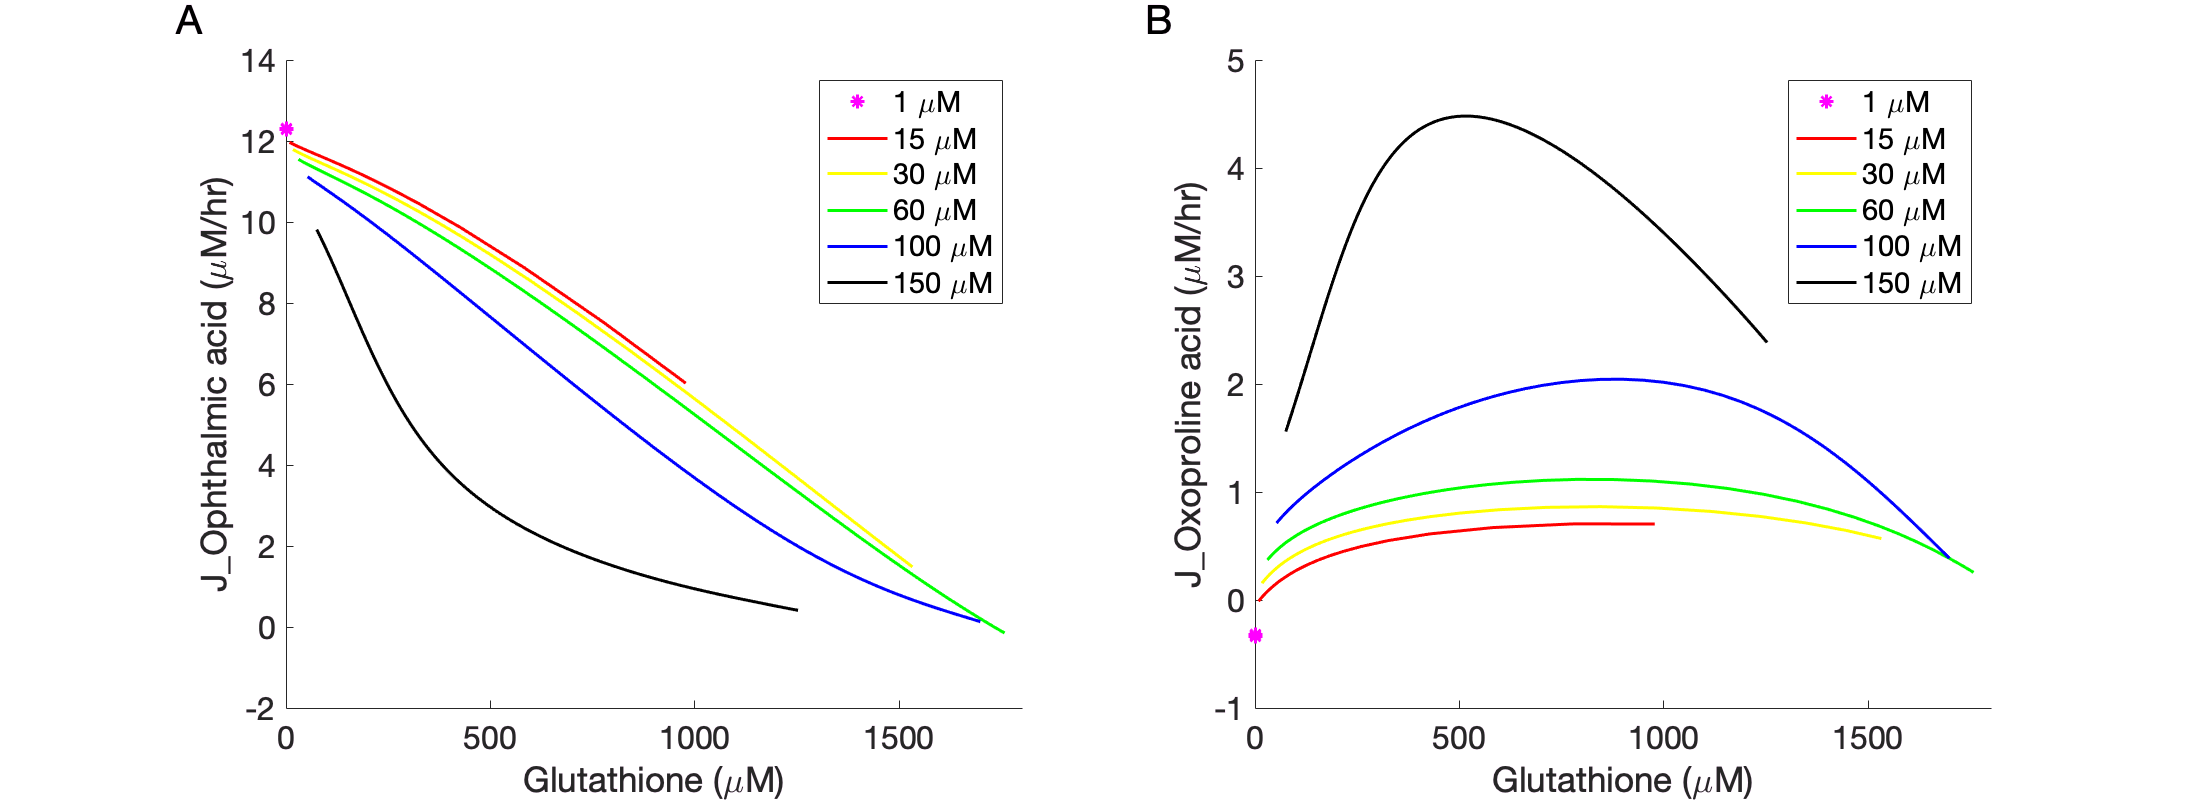

figure('position',[0, 0, 1100, 400])

% Fig. 6: GSH to OPA for varying methionine
subplot(1,2,1)
text(-0.15,1.1,'A','Units', 'Normalized', 'VerticalAlignment', 'Top', 'FontSize', 20); hold on
plot(D(ind1,3),D(ind1,4),'m*',D(ind15,3),D(ind15,4),'r',D(ind30,3),D(ind30,4),'y',D(ind60,3),D(ind60,4),'g',D(ind100,3),D(ind100,4),'b',D(ind150,3),D(ind150,4),'k')
xlabel('Glutathione (\muM)'); xlim([0 1800])
ylabel('J\_Ophthalmic acid (\muM/hr)')
legend('1 \muM','15 \muM','30 \muM','60 \muM','100 \muM','150 \muM')
hold off; 

% Fig. 7: GSH to OXO for varying methionine
subplot(1,2,2)
text(-0.15,1.1,'B','Units', 'Normalized', 'VerticalAlignment', 'Top', 'FontSize', 20); hold on
plot(D(ind1,3),D(ind1,5),'m*',D(ind15,3),D(ind15,5),'r',D(ind30,3),D(ind30,5),'y',D(ind60,3),D(ind60,5),'g',D(ind100,3),D(ind100,5),'b',D(ind150,3),D(ind150,5),'k')
xlabel('Glutathione (\muM)'); xlim([0 1800])
ylabel('J\_Oxoproline acid (\muM/hr)')
legend('1 \muM','15 \muM','30 \muM','60 \muM','100 \muM','150 \muM')
hold off;

export_fig('../Figures/Figure_S2','-pdf','-r200')

## Figure S3: Geenen figure 5 and 8

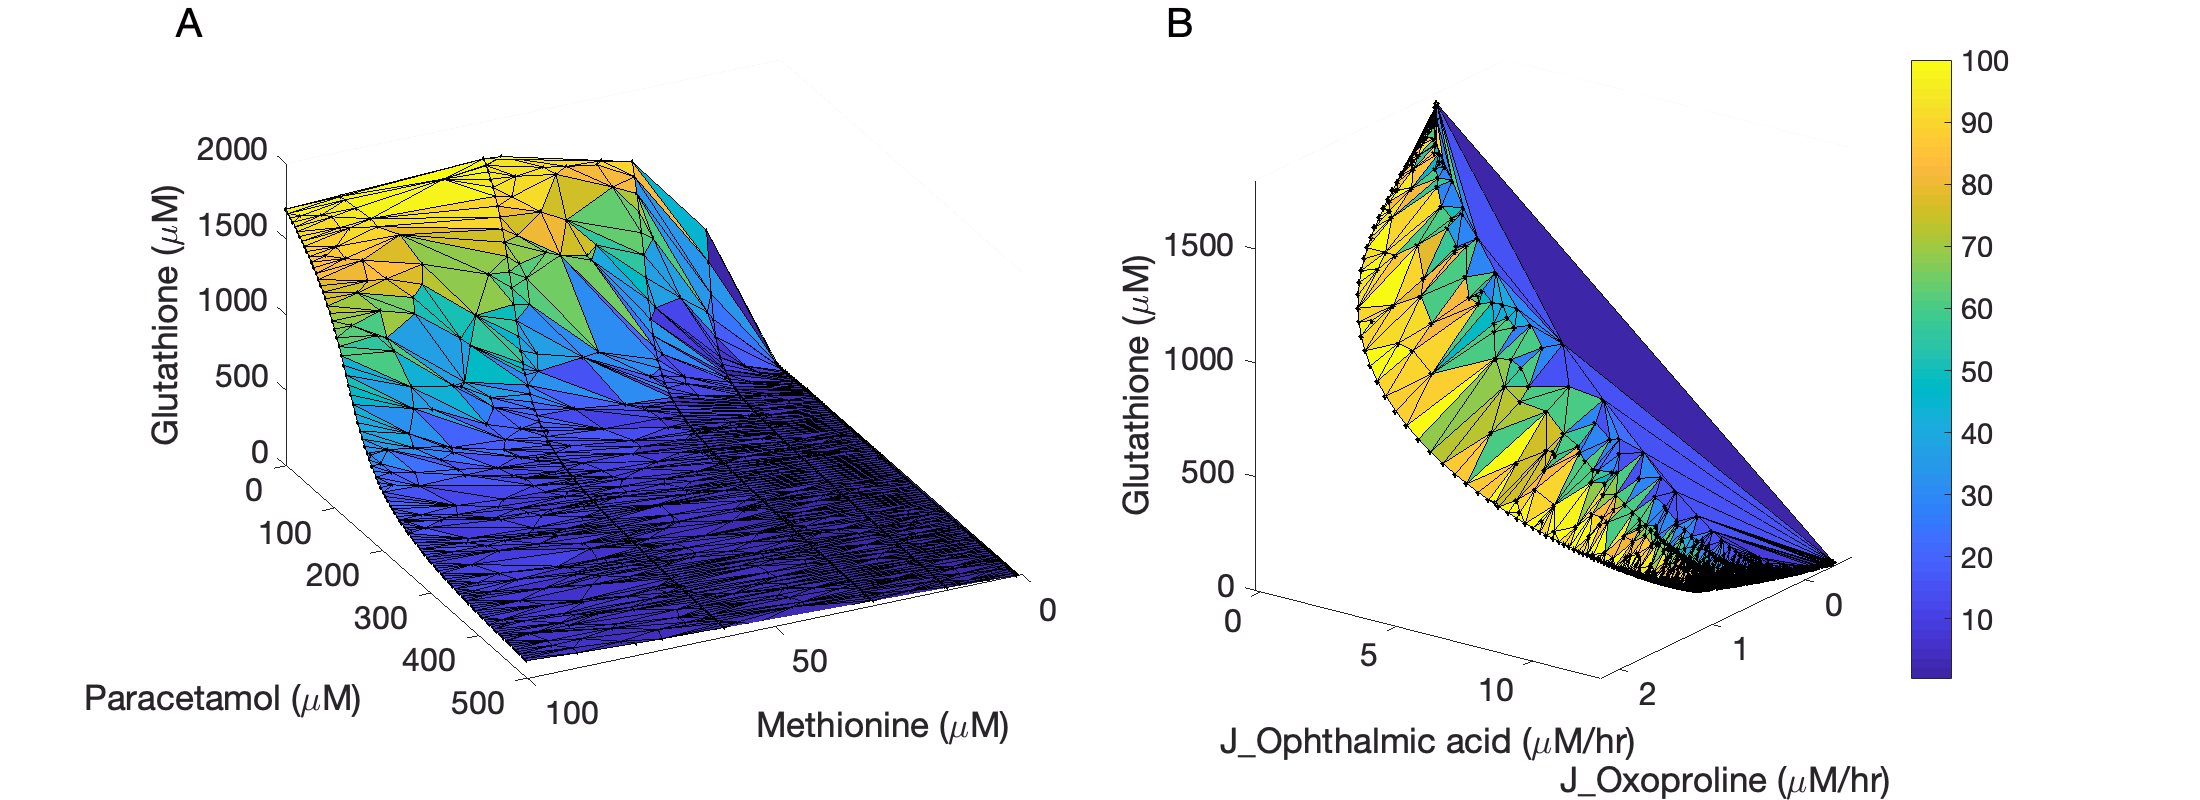

figure('position',[0, 0, 1100, 400])

% plot these curves only for methionine in [0-100]
ind = D(:,2) < 150;

% Fig. 5: 3D plot of paracetamol vs. methionine vs. glutathione
subplot(1,2,1)
text(-0.15,1.1,'A','Units', 'Normalized', 'VerticalAlignment', 'Top', 'FontSize', 20); hold on
x = D(ind,1); % para
y = D(ind,2);% methionine
z = D(ind,3);% glutathione
tri = delaunay(x,y); %x,y,z column vectors

trisurf(tri,x,y,z);
% shading interp
xlabel('Paracetamol (\muM)');xlim([0 500])
ylabel('Methionine (\muM)')
zlabel('Glutathione (\muM)')
view(-64,-38)

hLine = plot3(x,y,z,'ko');
% make transparent: http://undocumentedmatlab.com/blog/plot-markers-transparency-and-color-gradient
hLine.MarkerFaceColor = [0.5,0.5,0.5]; 
hLine.MarkerSize = 1;
drawnow
hMarkers = hLine.MarkerHandle;
hMarkers.FaceColorType = 'truecoloralpha';
hMarkers.FaceColorData = uint8(255*[1;0;0;0.2]);

hold off;
grid off
set(gca,'Layer','top')

% Fig. 8: 3D plot of OPA vs. OXO vs GSH colored by methionine levels
subplot(1,2,2)
text(-0.15,1.1,'B','Units', 'Normalized', 'VerticalAlignment', 'Top', 'FontSize', 20); hold on
x = D(ind,4); % OPA
y = D(ind,5); % OXO
z = D(ind,3); % glutathione
C = D(ind,2); % methionine
% delaunay is used to create a Delaunay triangulation of a set of points 
%     in 2D/3D space. A 2D Delaunay triangulation ensures that the circumcircle 
%     associated with each triangle contains no other point in its interior. 
%     This definition extends naturally to higher dimensions. 
%  
%     TRI = delaunay(X,Y) creates a 2D Delaunay triangulation of the points 
%     (X,Y), where X and Y are column-vectors. TRI is a matrix representing 
%     the set of triangles that make up the triangulation. The matrix is of
%     size mtri-by-3, where mtri is the number of triangles. Each row of TRI
%     specifies a triangle defined by indices with respect to the points.
tri = delaunay(x,y); %x,y,z column vectors

trisurf(tri,x,y,z,C);
% shading interp
view(-36,-20)
xlabel('J\_Ophthalmic acid (\muM/hr)'); xlim([-0.2 12.5])
ylabel('J\_Oxoproline (\muM/hr)'); ylim([-0.5 2.2])
zlabel('Glutathione (\muM)'); zlim([0 1800])
colorbar

hLine = plot3(x,y,z,'ko');
% make transparent: http://undocumentedmatlab.com/blog/plot-markers-transparency-and-color-gradient
hLine.MarkerFaceColor = [0.5,0.5,0.5]; 
hLine.MarkerSize = 2;
drawnow
hMarkers = hLine.MarkerHandle;
hMarkers.FaceColorType = 'truecoloralpha';
hMarkers.FaceColorData = uint8(255*[0;0;0;0.2]);

hold off;
grid off

export_fig('../Figures/Figure_S3','-pdf','-r200')

## Delaunay Triangulation of figure 8

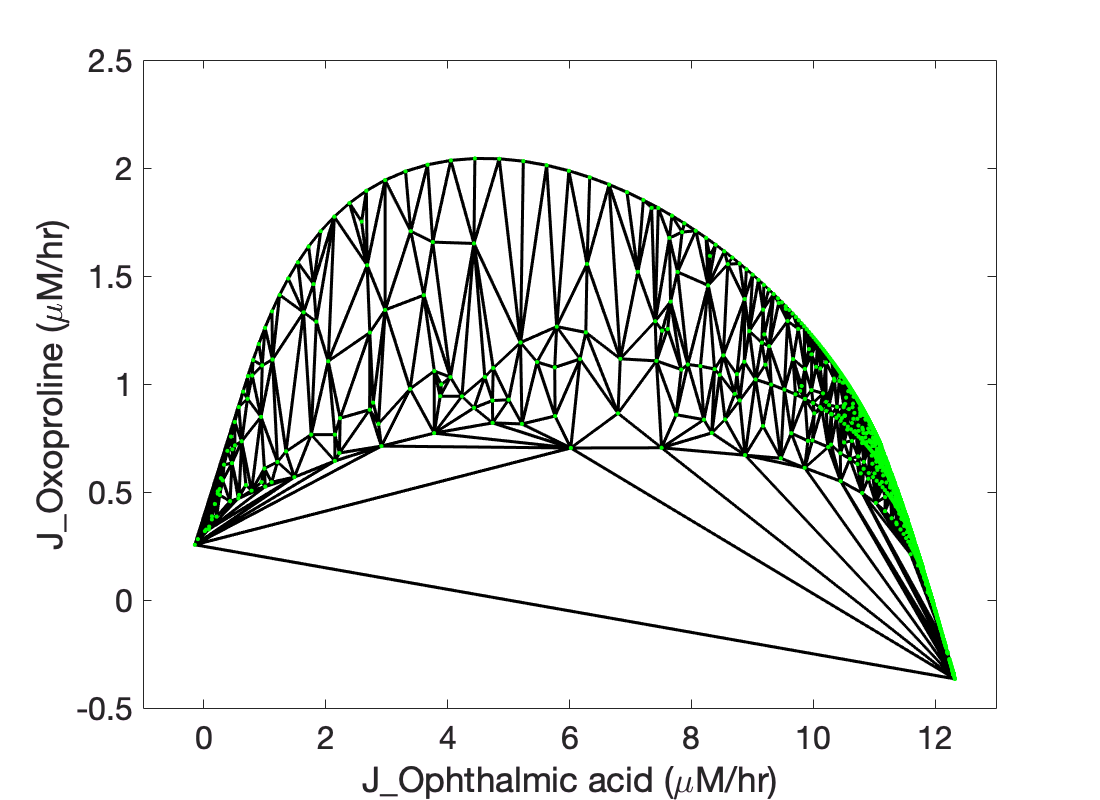

figure('position',[0, 0, 550, 400])

triplot(tri,x,y,'k','MarkerSize',5) % show the triangulaation for kicks
xlabel('J\_Ophthalmic acid (\muM/hr)'); xlim([-1 13])
ylabel('J\_Oxoproline (\muM/hr)'); ylim([-0.5 2.5])

hold on

plot(x,y,'.g')

% [xq,yq] = meshgrid(min(x):(range(x)/100):max(x), min(y):(range(y)/100):max(y));
% vq = griddata(x,y,z,xq,yq,'nearest');
% surf(xq,yq,vq)
% shading interp

export_fig('../Figures/Geenen_2012_fig_8_delaunay','-pdf','-r200')